file = fullfile("logs", "results.jsonl");

fid = fopen(file, 'r');

results = {};
line = fgetl(fid);
while ischar(line)
    % Decode each line from JSON
    obj = jsondecode(line);
    results{end+1} = obj; %#ok<*AGROW>
    line = fgetl(fid);
end

fclose(fid);

% Convert cell array of structs to struct array for easy indexing
if contains(file, 'single')
    results = vertcat(results{30:end});
else 
    results = [results{:}];
end

tab = struct2table(results);

if contains(file, "nojudge")
    decision = [""];
    for i = 1:height(tab)
        this = tab.agreement(i);
        this = this{:};
        if isempty(this) || ismember('error',fieldnames(this))
            decision(i) = "error";
        else
            decision(i) = string(this.decision);
        end
    end
    
    tab.decision = decision' ;
end

T = tab;


% Decision mapping with more synonyms
decisionMap = containers.Map( ...
    { ...
     'take action','''take action''','pull','''pull''','''pro''','pro', ...
     'do not take action','''do not take action''','don''t pull','''don''t pull''','dont_pull','''dont_pull''','''con''','con', ...
     'none','''none''','unclear','''unclear''', ...
     'error','''error''' ...
    }, ...
    [1 1 1 1 1 1  0 0 0 0 0 0 0 0  2 2 2 2  -1 -1] ...
);

T.decision = T.winner

T = 450×9 table
                  ts                               run_id                                                                                                                                                                                                topic                                                                                                                                                                                               model                  rounds    winner                                                                                                                                                             rationale                                                                                                                                                              transcript     decision

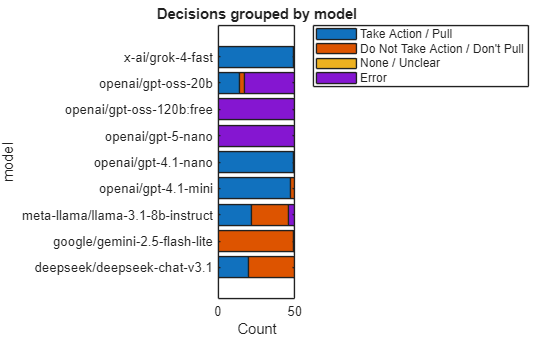

% Preallocate numeric vector for mapped decisions
mappedDecisions = zeros(height(T),1);
for i = 1:height(T)   
    if ~isempty(T.decision{i})
        mappedDecisions(i) = decisionMap(char(T.decision{i}));
    else 
        mappedDecisions(i) = -1;
    end
end

% Add mapped decision back to table
T.mappedDecision = mappedDecisions;

% Get unique models
models = unique(T.model);

% ----------------------------
% Choose grouping variable
% ----------------------------
if contains(file,"variants") && ismember("topic", T.Properties.VariableNames)
    groupVar = "topic";
else
    groupVar = "model";
end

groups = unique(T.(groupVar));

% Assign unique IDs if grouping by topic
if groupVar == "topic"
    groupIDs = (1:numel(groups))';
    % Add to table for reference
    T.topicID = zeros(height(T),1);
    for g = 1:numel(groups)
        idx = strcmp(T.topic, groups{g});
        T.topicID(idx) = groupIDs(g);
    end
end

% ----------------------------
% Count results per group
% ----------------------------
% Columns = [take action, don't take action, none/unclear, error]
counts = zeros(numel(groups),4);
for g = 1:numel(groups)
    idx = strcmp(T.(groupVar), groups{g});
    counts(g,1) = sum(T.mappedDecision(idx) == 1);
    counts(g,2) = sum(T.mappedDecision(idx) == 0);
    counts(g,3) = sum(T.mappedDecision(idx) == 2);
    counts(g,4) = sum(T.mappedDecision(idx) == -1);
end

% ----------------------------
% Plot horizontal stacked bar chart
% ----------------------------
figure;
barh(counts,'stacked')
if contains(file,"variants")
    set(gca,'YTick',1:numel(groups),'YTickLabel',labels)
else
    set(gca,'YTick',1:numel(groups),'YTickLabel',groups)
end
ylabel(char(groupVar))
xlabel('Count')
legend({'Take Action / Pull','Do Not Take Action / Don''t Pull','None / Unclear', 'Error'}, ...
       'Location','bestoutside')
title(['Decisions grouped by ' char(groupVar)])



figure;
X = categorical(T.(groupVar));
explode = {};

% pie(X,explode,labels)
% 
% % Plot grouped stacked bar chart
% figure;
% bar(counts,'stacked')
% set(gca,'XTickLabel',models,'XTickLabelRotation',45)
% ylabel('Count')
% legend({'Take Action','Do Not Take Action','None','Error'})
% title('Model Decisions')
% 
% figure;
% barh(counts,'stacked')
% set(gca,'YTickLabel',models)
% ylabel('Model')
% xlabel('Count')
% legend({'Take Action','Do Not Take Action','None','Error'}, 'Location','bestoutside')
% title('Model Decisions (Horizontal)')